# A Brief introduction to MatLab

## Author Discharge? 

For this Brief I strongly recomend to read the python one first, or side by side. That's because i created this one based on the another one,

because, i  thought it's was a good idea to compare the same ideas  ( seems easy to me understand something comparing it with another thing that (*I think*) that I understand.

Anyways the idea of this is just get de BASICS really really basics tools to work, there a loot of shortcuts, commands and things that you have to discover by yourself (that's what's being a proffesional means i think).

I have some things that I did not say yesterday, beside the fact that my speaking abilities are more than pittyful,

my writting ones aren't good neither, so I hope that I commited the minimun (or at least an acceptable quiantity) of errors. I have to remark that i'm not using a corrector here,, i have no idea how to.

Another thing that I want to remark it's that as matlab, unlike python, it's NOT a free language or platform, so if you don't buy it (or well, let's not let that written ) you cannot use it. 

That's another thing that i believe the python brief could help with. Python it's free, and in adition you don't have to install nothing to use colaboratory from google. so you can run code,

make som simple experiments and what your imagination allows you there. In this case, you could not modify and re-run the codes  to make tests or apply ideas. First you have to install matlab.

There are some free and open platforms very simmilar to matlab like octave, but the lack of some tools make feel like python is a better option than those.

## Last But not least:

I'm a little rusty with matlab, so if you see an error or not optimal way to do something, please forgive me, and here you got my e-mail :

ulises.bussi@unq.edu.ar                 <-- the institutional one

ulisesbussi@gmail.com                   <-- personal one (i'd rather that you write here, because i don't check the institutional every day)

with nothing more to say y let you with the notes.

Saludos

Ulises

In this **notebook** we are going to make a lite introduction to Matlab.(based of what we saw yesterday in python

The main difference between matlab and Python is that Matlab is an mathematical oriented language (even his name comes from MATrix - LABoratory ) 

what respects to variable types there are  many of them {, we have no time to learn them all, that's why we are going to make a little list of them and show how to manipulate them:

-  Bool: a boolean value it can take either 'True' or 'False' 

- Number : number variables can be diferent subtypes like (integers, float, complex).

- Str: an string of characters

- Numeric Array: it cpuld be something like a vector, or matrix or ndim arrays.

- Cells : most likely a python list, it can contain mixed types.

- Struct: as far as I know (not an absolute true) it's an analog of Dictionary in  python: it's a list where every element have an user defined identificator


boolVar = true;
myPrint(boolVar)

I'm a logical variable, and my value is: 


   1




floatVar=3.44;
myPrint(floatVar)

I'm a double variable, and my value is: 


    3.4400





strVar = 'Hola!';
myPrint(strVar)

I'm a char variable, and my value is: 


Hola Tamiu!



arrayVar = [1,2,3,4];
myPrint(arrayVar)

I'm a double variable, and my value is: 


     1     2     3     4




cellVar = {'soap', 'meat', 'eggs', 6, strVar}

cellVar =     'soap'    'meat'    'eggs'    [6]    'Hola Tamiu!'


myPrint(cellVar)

I'm a cell variable, and my value is: 


    'soap'    'meat'    'eggs'    [6]    'Hola Tamiu!'




disp('my first element has the index 1, and it''s value is:'),disp ( cellVar(1))

my first element has the index 1, and it's value is:
    'soap'




%Here in matlab, arrays, cells etc starts in the index 1!
%and we use  () to access it


structVar = struct('identificator1', 33, 'aList',cellVar,'cats', 'are Awesome!');%, 33: "It's a number!")
myPrint(structVar)

I'm a struct variable, and my value is: 


  1×5 struct array with fields:

    identificator1
    aList
    cats



%note that here we CAN NOT use a number as identificator, necesarily it has to be a string
% to access to one of this fields we do var.field

disp('I have fields as identificator, and my fields are:'),disp(fieldnames(structVar))

I have fields as identificator, and my fields are:
    'identificator1'
    'aList'
    'cats'



Lets go with some math

a = 3;
b = 4;

a+b

ans = 7

a-b

ans = -1

a*b

ans = 12

a/b

ans = 0.7500

a>b

ans =    0


a^b % i.e. a^b

ans = 81

mod(27,6) % integer division mod

ans = 3

abs(-7)

ans = 7

max(5,6)

ans = 6

(3+2j) * (3+2i)

ans =    5.0000 +12.0000i


we can use comparations, as we saw in the above cell, let's take some workflow functions like **if** or **for**

first of all, when we work with matlab, we don't use braces when we want to start or end a workflow function. we just start it and when we want to end  it we write end ... better look for examples:

a = 57 ;
b = 50;

if a>b
  disp([a, 'is greater than ',b])
  a =a- 35
  %A lot of other lines, indentation it's only recomended not required
elseif a< 1
  disp('else-if condition')
else
  disp('else condition')  
end

9is greater than 2


a = 22

  
  
if a>b
  disp([a, 'is greater than ',b])
  a = a+ 35;
else
  disp([' ', a, ' is smaller than ',b])  
end

  is smaller than 2


# 'if' operator

---

like almost any other language, the general way to use an if-conditional is: 

if test 

*        what to do if test is true*

elif test2

*        what to do if test2 is true*

elif anotherTest :

*        what to do if anotherTest*

 else

*          what to do if anotherTest bites the dust*

end 

 if we need to combine diferents tests, we can use "and" , "or", "not", "==", "<", "<=", ">", "=>" as operators and many others

 but not actually and, instead we use & or && for the or | or ||, i think it's like in C++ but y might missing something 

# 'for' operator

---

as in many languages the for operator is an iterator that allows us to make a repetitive work. 

�with slights differences with c++:

here it's not necesary to put the increment, and replace the semicolon with colon ; -> :

but we can define the range of iteration with se shape start:step:stop (atention to the step between start and stop in difference of python where the step was the last one

for i=0:0.5:3  %it means i will be the element in the actual iteration i.e. 0, 1, 2, 3 
  disp(i)
end

     0



    0.5000



     1



    1.5000



     2



    2.5000



     3



for i=0:3  %it means i will be the element in the actual iteration i.e. 0, 1, 2, 3 
  disp(i)
end

     0



     1



     2



     3



Now to do some complex math, we don't need to include librarys, the matlab 'import them implicity'. So let's do some vector sum, products, elementwise prod, matrix vector... bla bla bla

array1 =  [1,2,3] ; 
array2 =  [1,2,1];

myPrint(array1)

I'm a double variable, and my value is: 


     1     2     3



disp(['My shape is:']), disp(size(array1))

My shape is:
     1     3



array1+array2

ans =      2     4     4


array1-array2

ans =      0     0     2


array1.*array2 %elementWise Operation

ans =      1     4     3


array1./array2 %elementwise

ans =      1     1     3


array1*(array2') %im transposing the second array to dimensions to match

ans = 8

array1/array2 %actually not sure what's doin

ans = 1.3333

mat = [1,2,3; 1 0 0; 0 0 1];
mat*array1'

ans =     14
     1
     3


nDimMat =randn(2,3,4,5,3)

nDimMat = 
(:,:,1,1,1) =

    0.0302    1.2511   -0.3573
   -0.0425   -2.3254    0.5946


(:,:,2,1,1) =

   -1.3973    0.4908   -0.3433
    0.5282    0.3795    0.4119


(:,:,3,1,1) =

   -1.2793    1.1549   -0.5065
    1.1817    1.7531    0.5375


(:,:,4,1,1) =

    0.5864    1.3349   -0.4391
   -0.0401    0.5152    0.6828


(:,:,1,2,1) =

    0.2529   -0.3218   -1.1458
    0.2165   -0.1928    0.2382


(:,:,2,2,1) =

    0.5996   -0.9578   -0.4782
   -1.0422    0.5906    0.7759


(:,:,3,2,1) =

    0.6440    0.5606   -0.0225
    0.4662   -0.2203   -1.9215


(:,:,4,2,1) =

   -1.1834   -2.1847    1.6673
    0.1998    0.1260    0.7273


(:,:,1,3,1) =

   -1.4331    1.1728    0.4232
    1.1307   -1.5339    0.5806


(:,:,2,3,1) =

    0.5713   -1.6583   -2.5212
    2.8264   -0.1237    0.8750


(:,:,3,3,1) =

    0.5565   -0.9942    0.5819
    0.7078    0.2584    0.4731


(:,:,4,3,1) =

    0.2831    0.2459    0.3455
   -0.0222   -0.2230   -0.2812


(:,:,1,4,1) =

   -0.7473   -0.2072    0.

# Plots

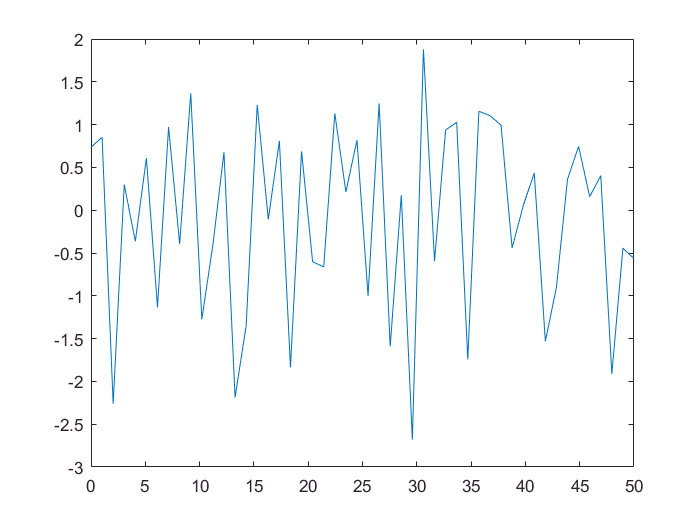

x = linspace(0,50,50);
y = randn(50,1);
figure(1)
plot(x,y)

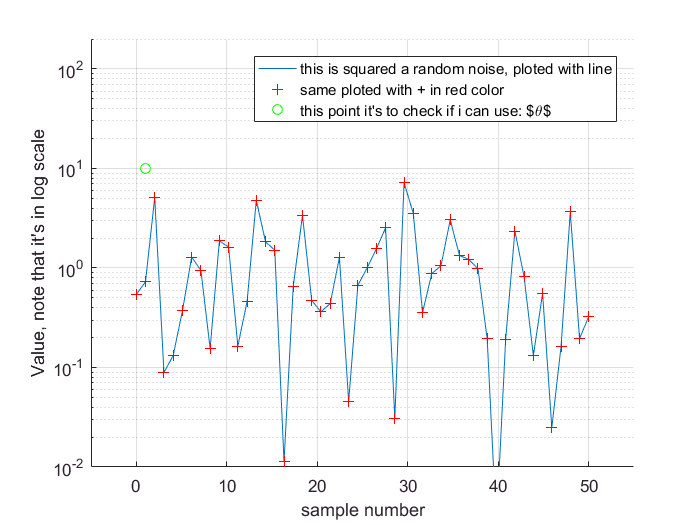

labelWithLatex = 'this point it''s to check if i can use: $\theta$';
 
figure(2);
ax = gca();
hold on ;% <- if we want to se more than one plot in the same figure
plot(x,y.^2);
plot(x,y.^2,'r+');
plot(1,10,'go');
label1 ='this is squared a random noise, ploted with line';
label2='same ploted with + in red color';
legend( label1,label2,labelWithLatex)
xlim([-5,55])
ylim([0.01, 200])
ax.YScale='log';

xlabel('sample number')
ylabel('Value, note that it''s in log scale')
grid on

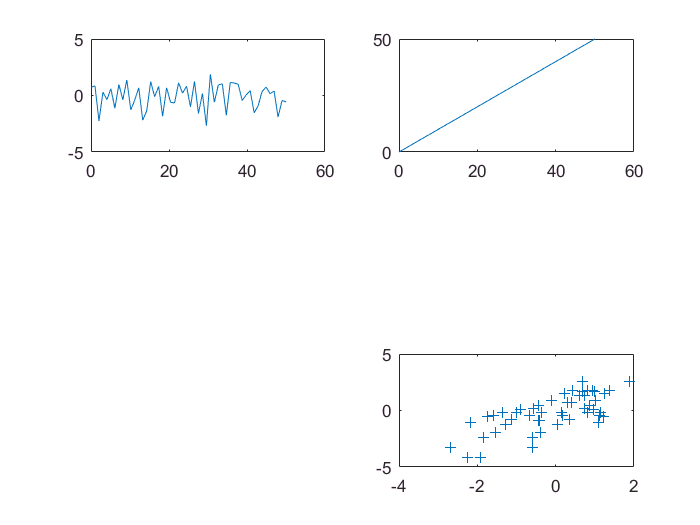

%to make subplots
figure(3)
ncols = 3;
nrows = 2;
index = 1;
subplot(ncols,nrows,index)
plot(x,y)
subplot(3,2,2)
plot(x,x)
subplot(3,2,6)
plot(y,y+y(end:-1:1),'+')

The image shape is
   640   480     3



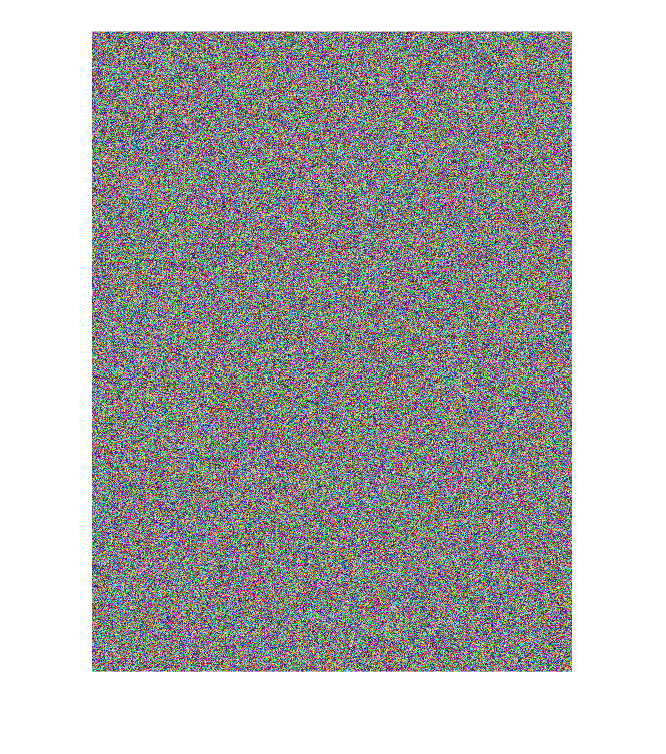

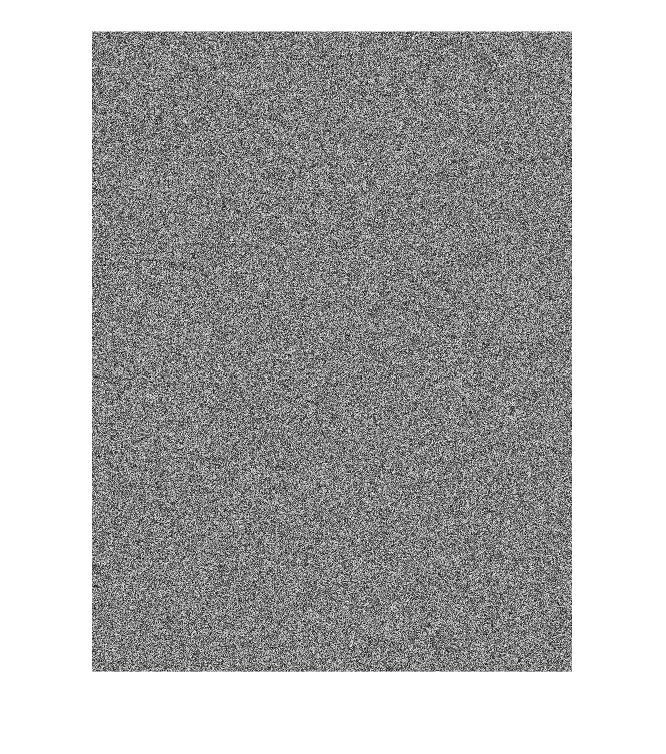

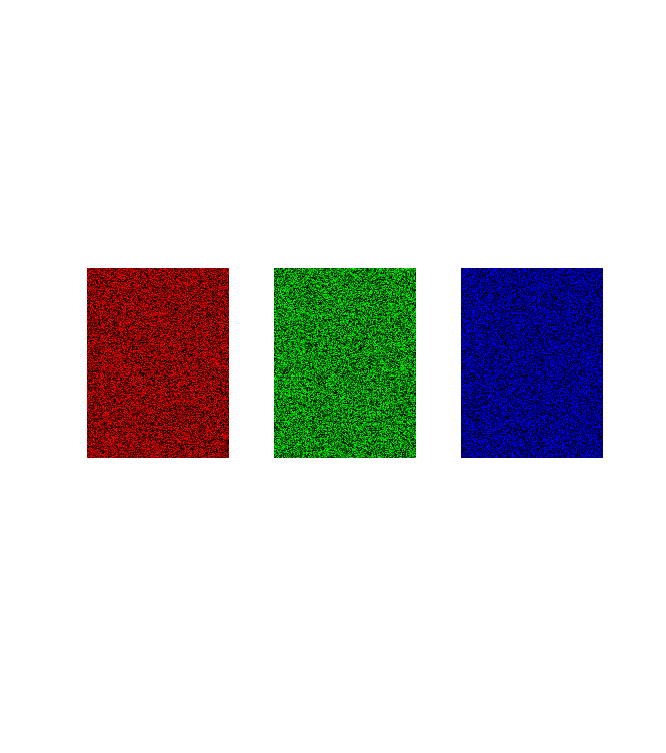

function myPrint(var)

   disp(['Soy una variable ' , class(var) ,', y mi valor es: '])
   disp(var)
end
   